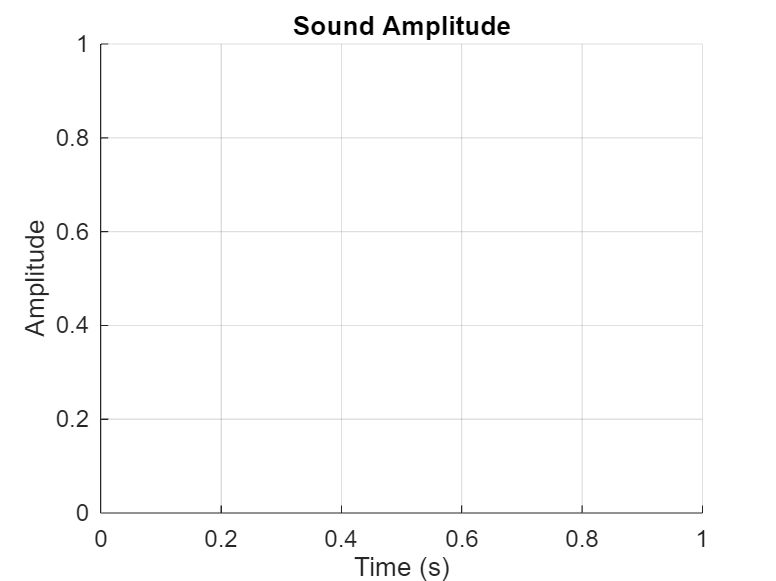

clear; clc;
filename = 'test1715.csv';

% Read CSV file
data = readcell(filename, 'Delimiter', ',');

% Extract data types and numerical values
data_types = data(:, 1);  % First column:('Sound' or 'Accel')
numerical_data = data(:, 2:end);  % All other columns: Numerical values

% Replace empty or non-numeric cells with 0, for processing
numerical_data(cellfun(@isempty, numerical_data)) = {0};
numerical_data(~cellfun(@isnumeric, numerical_data)) = {0};

% Logical indexing for sound and accelerometer data
sound_indices = strcmp(data_types, 'Sound');  
accel_indices = strcmp(data_types, 'Accel'); 

% Extract sound data (ensure numeric values)
sound_data = cell2mat(numerical_data(sound_indices, 1));

% Extract accelerometer data (ensure numeric values)
accel_data = cell2mat(numerical_data(accel_indices, :));

sound_sampling_rate = 44100;  % Microphone sampling rate (Hz)
accel_sampling_rate = 50;     % Accelerometer sampling rate (Hz)


numSoundSamples = length(sound_data);
time_sound = (0:numSoundSamples-1) / sound_sampling_rate;

%Amplitude Plot
figure;
plot(time_sound, sound_data, 'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sound Amplitude');
grid on;

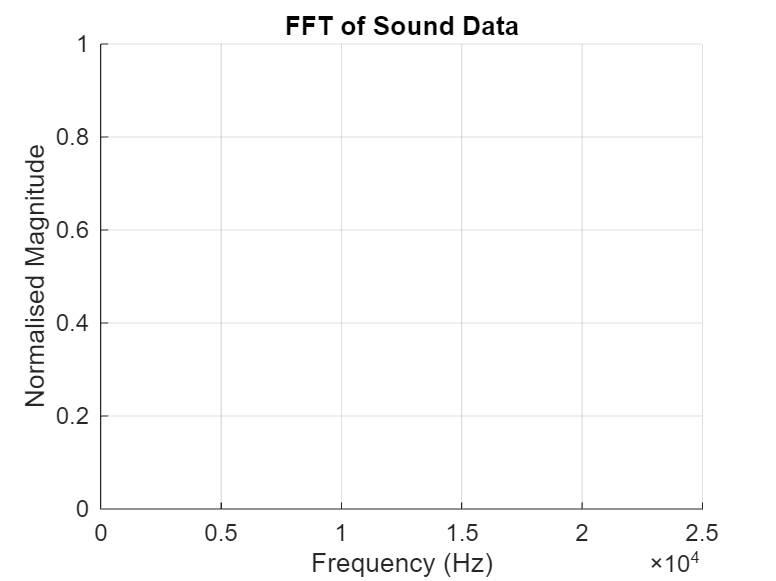


% Perform FFT of Sound
sound_data = sound_data - mean(sound_data);
windowed_sound = sound_data .* hann(length(sound_data));
N = length(windowed_sound);
fft_data = fft(windowed_sound);
f = (0:N-1) * (sound_sampling_rate / N);
fft_magnitude = abs(fft_data(1:floor(N/2))) / max(abs(fft_data));
f = f(1:floor(N/2));

%FFT Plot
figure;
plot(f, fft_magnitude);
xlabel('Frequency (Hz)');
ylabel('Normalised Magnitude');
title('FFT of Sound Data');
grid on;
xlim([0, 25000]);


window_length = 1024;
overlap = 512;
nfft = 1024;

% Spectrogram Plot
figure;
spectrogram(sound_data, hann(window_length), overlap, nfft, sound_sampling_rate, 'yaxis');

Error using spectrogram
Expected X to be a vector.

Error in spectrogram (line 178)
validateattributes(x,{'single','double'},...

title('Spectrogram of Sound Data');
colorbar;
ylabel('Frequency (kHz)');
xlabel('Time (s)');
ylim([0, 22]);

% Plot Acceleration 
numAccelSamples = size(accel_data, 1);
time_accel = (0:numAccelSamples-1) / accel_sampling_rate;

figure;
subplot(3, 1, 1);
plot(time_accel, accel_data(:, 1), 'r');
xlabel('Time (s)');
ylabel('X Acceleration (g)');
title('X-Axis Acceleration');
grid on;

subplot(3, 1, 2);
plot(time_accel, accel_data(:, 2), 'g');
xlabel('Time (s)');
ylabel('Y Acceleration (g)');
title('Y-Axis Acceleration');
grid on;

subplot(3, 1, 3);
plot(time_accel, accel_data(:, 3), 'b');
xlabel('Time (s)');
ylabel('Z Acceleration (g)');
title('Z-Axis Acceleration');
grid on;

figure;
plot(time_accel, accel_data(:, 1), 'r');
xlabel('Time (s)');
ylabel('X Acceleration (g)');
title('X-Axis Acceleration');
grid on;

figure;
plot(time_accel, accel_data(:, 2), 'g');
xlabel('Time (s)');
ylabel('Y Acceleration (g)');
title('Y-Axis Acceleration');
grid on;

figure;
plot(time_accel, accel_data(:, 3), 'b');
xlabel('Time (s)');
ylabel('Z Acceleration (g)');
title('Z-Axis Acceleration');
grid on;